a)

stat = readtable("UCLA_EE_grad_2030.csv");
y = (stat{:,3} + 1)/2;
GPA = stat{:,1};
GRE = stat{:,2};

N = length(y);

Py0 = sum(y == 0) / N

Py0 = 0.7900


GPAmu0 = sum(GPA(y == 0)) / sum(y == 0)

GPAmu0 = 1.8678

GPAmu1 = sum(GPA(y == 1)) / sum(y == 1)

GPAmu1 = 3.1637

GPAvar = 1 / N * (norm(GPA(y == 0) - GPAmu0)^2 + norm(GPA(y == 1) - GPAmu1)^2)

GPAvar = 0.4457


GREmu0 = sum(GRE(y == 0)) / sum(y == 0)

GREmu0 = 1.9673

GREmu1 = sum(GRE(y == 1)) / sum(y == 1)

GREmu1 = 2.9590

GREvar = 1 / N * (norm(GRE(y == 0) - GREmu0)^2 + norm(GRE(y == 1) - GREmu1)^2)

GREvar = 0.4745

b)

theta = 1 - Py0;
b1 = (GPAmu1^2 - GPAmu0^2) / (2 * GPAvar) - log(theta / (1 - theta));
b1 = b1 * GPAvar / (GPAmu1 - GPAmu0);
b1

b1 = 2.9714

b2 = (GREmu1^2 - GREmu0^2) / (2 * GREvar) - log(theta / (1 - theta));
b2 = b2 * GREvar / (GREmu1 - GREmu0);
b2

b2 = 3.0971

miss = 0;
for i = 1:N
    if (GPA(i) > b1) ~= y(i)
        miss = miss + 1;
    end
end
GPAacc = 1 - miss / N;
GPAacc

GPAacc = 0.8600

miss = 0;
for i = 1:N
    if (GRE(i) > b2) ~= y(i)
        miss = miss + 1;
    end
end
GREacc = 1 - miss / N;
GREacc

GREacc = 0.8700

c)

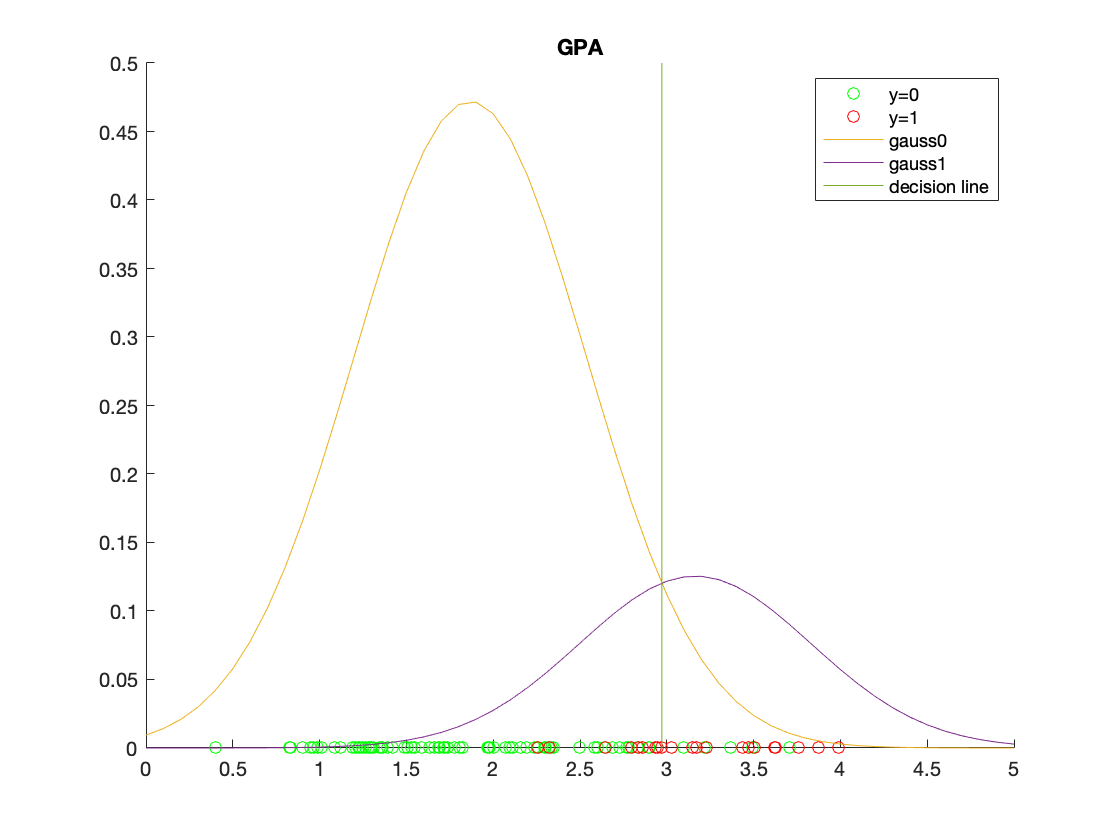

figure(1);
hold on;
scatter(GPA(y == 0), zeros(sum(y == 0), 1), 'green');
scatter(GPA(y == 1), zeros(sum(y == 1), 1), 'red');
gauss0 = Py0 * normpdf((0:0.1:5), GPAmu0, sqrt(GPAvar));
gauss1 = theta * normpdf((0:0.1:5), GPAmu1, sqrt(GPAvar));
plot((0:0.1:5), gauss0);
plot((0:0.1:5), gauss1);
plot(b1 * ones(51, 1), (0:0.01:0.5));
title("GPA");
legend('y=0', 'y=1', 'gauss0', 'gauss1', 'decision line');

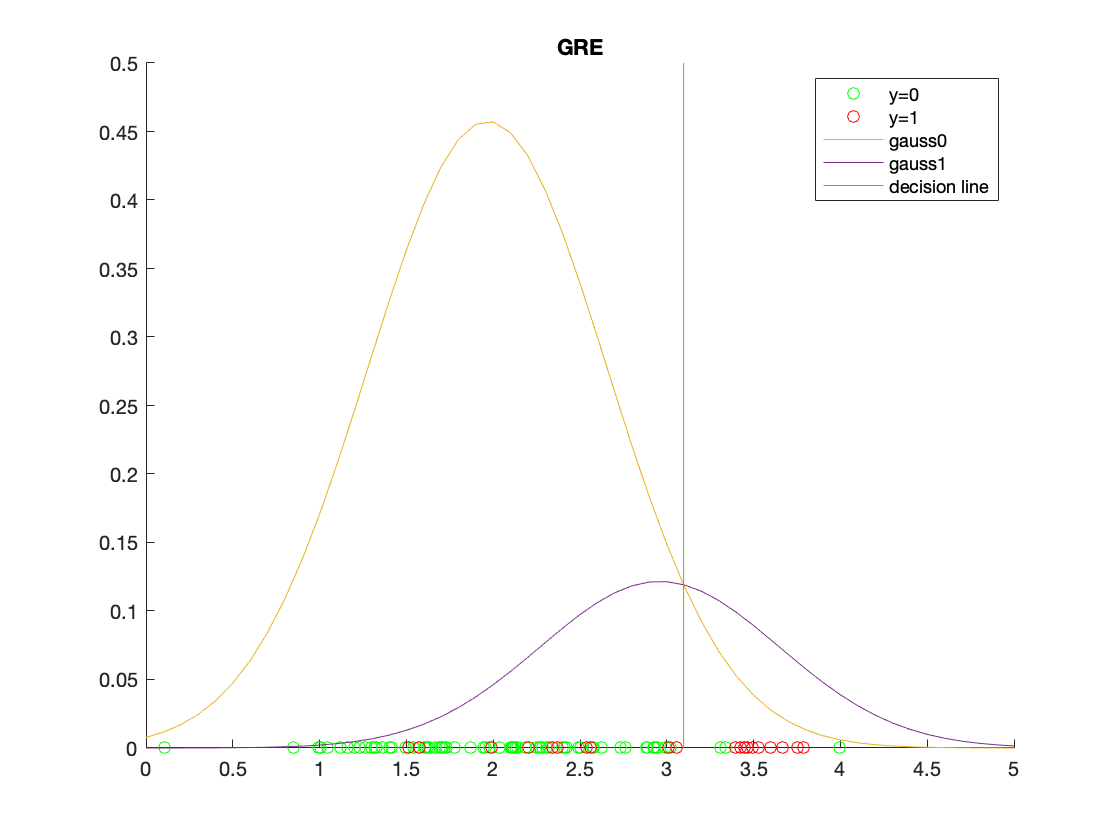


figure(2);
hold on;
scatter(GRE(y == 0), zeros(sum(y == 0), 1), 'green');
scatter(GRE(y == 1), zeros(sum(y == 1), 1), 'red');
gauss0 = Py0 * normpdf((0:0.1:5), GREmu0, sqrt(GREvar));
gauss1 = theta * normpdf((0:0.1:5), GREmu1, sqrt(GREvar));
plot((0:0.1:5), gauss0);
plot((0:0.1:5), gauss1);
plot(b2 * ones(51, 1), (0:0.01:0.5));
title("GRE");
legend('y=0', 'y=1', 'gauss0', 'gauss1', 'decision line');

(d)

Py0

Py0 = 0.7900

GPAmu0

GPAmu0 = 1.8678

GPAmu1

GPAmu1 = 3.1637

GPAvar0 = 1 / (sum(y == 0)) * norm(GPA(y == 0) - GPAmu0)^2

GPAvar0 = 0.5066

GPAvar1 = 1 / (sum(y == 1)) * norm(GPA(y == 1) - GPAmu1)^2

GPAvar1 = 0.2163

GREmu0

GREmu0 = 1.9673

GREmu1

GREmu1 = 2.9590

GREvar0 = 1 / (sum(y == 0)) * norm(GRE(y == 0) - GREmu0)^2

GREvar0 = 0.4668

GREvar1 = 1 / (sum(y == 1)) * norm(GRE(y == 1) - GREmu1)^2

GREvar1 = 0.5035

(e)

gpaa = 1/2 * (1/GPAvar0 - 1/GPAvar1);
gpab = GPAmu1/GPAvar1 - GPAmu0/GPAvar0;
gpac = 1/2 * (GPAmu0^2/GPAvar0 - GPAmu1^2/GPAvar1) + log(theta / (1 - theta) * sqrt(GPAvar0/GPAvar1));
gpar = roots([gpaa, gpab, gpac]);
gpar

gpar =     5.3557
    2.9026


grea = 1/2 * (1/GREvar0 - 1/GREvar1);
greb = GREmu1/GREvar1 - GREmu0/GREvar0;
grec = 1/2 * (GREmu0^2/GREvar0 - GREmu1^2/GREvar1) + log(theta / (1 - theta) * sqrt(GREvar0/GREvar1));
grer = roots([grea, greb, grec]);
grer

grer =   -24.4141
    3.1038


miss = 0;
for i = 1:N
    x = GPA(i);
    if (x^2 * gpaa + x * gpab + gpac > 0) ~= y(i)
        miss = miss + 1;
    end
end
GPAacc = 1 - miss / N

GPAacc = 0.8800

miss = 0;
for i = 1:N
    x = GRE(i);
    if (x^2 * grea + x * greb + grec > 0) ~= y(i)
        miss = miss + 1;
    end
end
GREacc = 1 - miss / N

GREacc = 0.8700

(f)

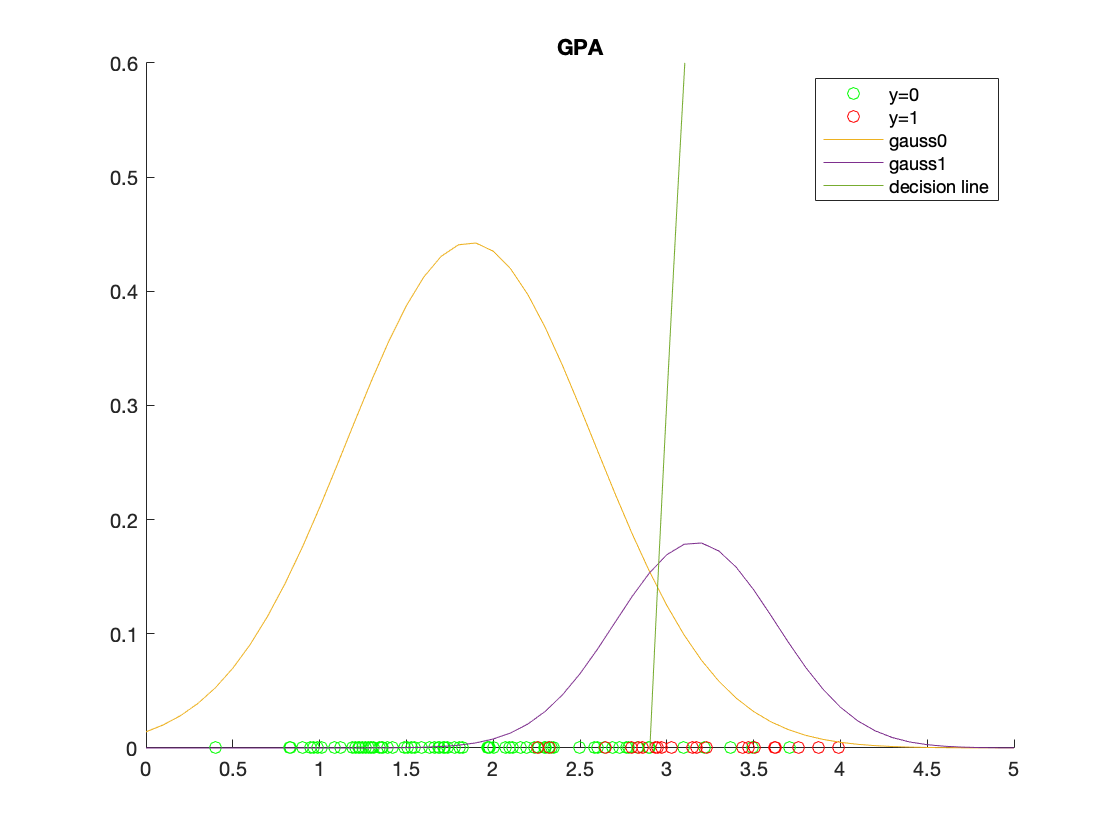

xpt = (0:0.01:5);
figure(3);
hold on;
scatter(GPA(y == 0), zeros(sum(y == 0), 1), 'green');
scatter(GPA(y == 1), zeros(sum(y == 1), 1), 'red');
gauss0 = Py0 * normpdf((0:0.1:5), GPAmu0, sqrt(GPAvar0));
gauss1 = theta * normpdf((0:0.1:5), GPAmu1, sqrt(GPAvar1));
plot((0:0.1:5), gauss0);
plot((0:0.1:5), gauss1);
ylim([0,0.6]);
plot(xpt, gpaa * xpt.^2 + gpab * xpt + gpac);
title("GPA");
legend('y=0', 'y=1', 'gauss0', 'gauss1', 'decision line');

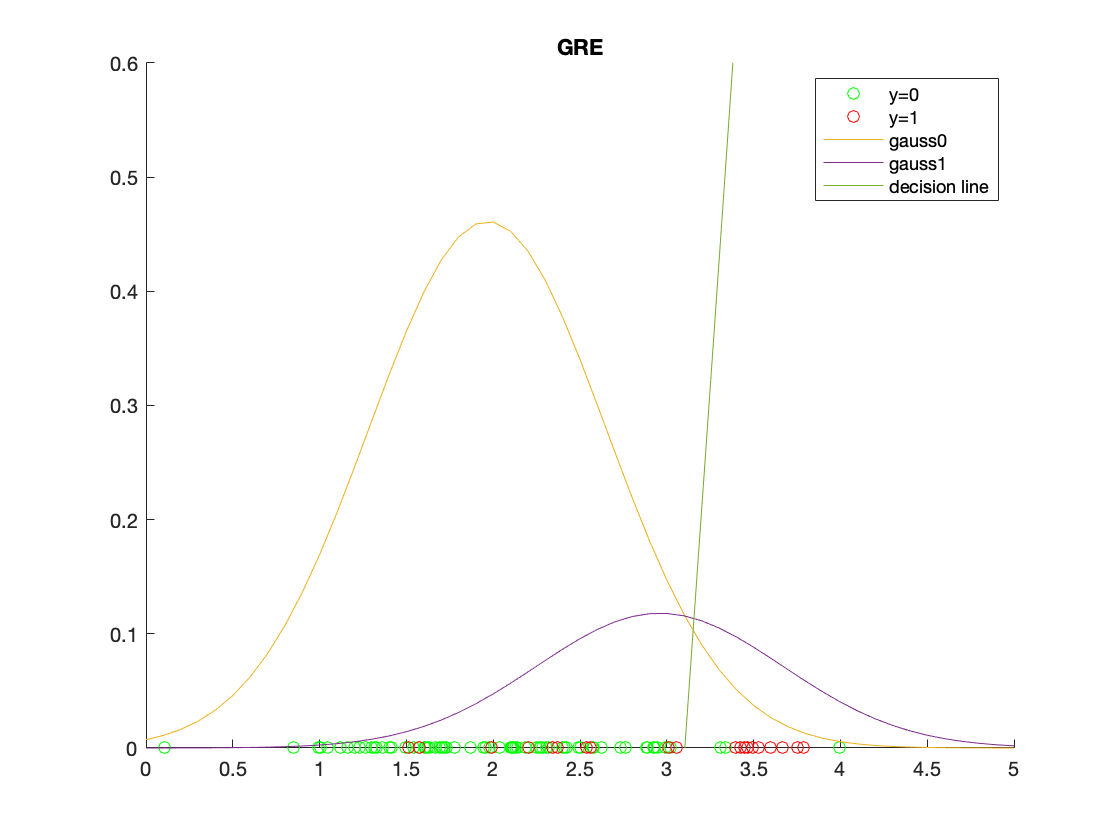


figure(4);
hold on;
scatter(GRE(y == 0), zeros(sum(y == 0), 1), 'green');
scatter(GRE(y == 1), zeros(sum(y == 1), 1), 'red');
gauss0 = Py0 * normpdf((0:0.1:5), GREmu0, sqrt(GREvar0));
gauss1 = theta * normpdf((0:0.1:5), GREmu1, sqrt(GREvar1));
plot((0:0.1:5), gauss0);
plot((0:0.1:5), gauss1);
ylim([0,0.6]);
plot(xpt, grea * xpt.^2 + greb * xpt + grec);
title("GRE");
legend('y=0', 'y=1', 'gauss0', 'gauss1', 'decision line');